## **Finite Element Method**

clc; 
clear;
syms x f(x) u_e(x) h

a=1

a = 1

c =3*x

$$c = 3\,x$$


% No of elements
e = 8;
% No of Nodal points
n =e+1;

f(x) = 4*x^2 - 2*x -4;

deqn = a*diff(u_e,x,2)+c*u_e == f;

Value1 = 0;
Value2 = 1;

ic = u_e(0) == Value1;
d_ue(x)= diff(u_e,x);
%ic2 = d_ue(1) == Value2;

ic2=u_e(1) == Value2;

u_exact = dsolve(deqn,[ic ic2]);
exact_sol_f = u_exact;
% domain of X
x0 = 0;
xn = 1;
% Element length
h_num = (xn - x0) / e;

% At nodel point the value of x
X = (x0:h_num:xn)';

% Source vector Initialization 
f_x = sym(zeros(n, 1));

% Calculate f(x) for each x value symbolically and store in the vector
for i = 1:n
    f_x(i) = subs(f, x, X(i));
end

% Source vector Initialization 
c_x = sym(zeros(n, 1));

% Calculate f(x) for each x value symbolically and store in the vector
for i = 1:n
    c_x(i) = subs(c, x, X(i));
end


% Define Shape Functions
phi_1 = 1 - x/h;
phi_2 = x/h;

phi_e = [phi_1; phi_2];

% Local stiffness matrix
KL1 = zeros(2, 2, 'sym');
KL3_Ten3 = zeros(2, 2,2, 'sym');
F_Mat = zeros(2, 2, 'sym');

for N = 1:2
    for M = 1:2
        for K = 1:2
            KL3_Ten3(N, M,K) = int(-1 * phi_e(N) * phi_e(M)* phi_e(K), x, 0, h);
        end
        KL1(N, M) = int(a * diff(phi_e(N), x) * diff(phi_e(M), x), x, 0, h);
        F_Mat(N, M) = int(-1* phi_e(N) * phi_e(M), x, 0, h);
    end
end

% Display the local stiffness matrix
disp('Local Stiffness Matrix some element e:');

Local Stiffness Matrix some element e:


disp(KL1);

$$\left(\begin{array}{cc} \frac{1}{h} & -\frac{1}{h}\\ -\frac{1}{h} & \frac{1}{h} \end{array}\right)$$

disp('Local C_NM Matrix some element e:');

Local C_NM Matrix some element e:


disp(F_Mat);

$$\left(\begin{array}{cc} -\frac{h}{3} & -\frac{h}{6}\\ -\frac{h}{6} & -\frac{h}{3} \end{array}\right)$$



% Substitute values into the local  matrices
KL1_sub = subs(KL1, h, h_num);
KL3_Ten3_sub = subs(KL3_Ten3, h, h_num);
F_Mat_sub = subs(F_Mat, h, h_num);

% % Display the substituted local stiffness matrix
% disp('Substituted values of a c and h in Local Stiffness Matrix:');
% disp(KL1_sub);
% disp('Substituted value h in Local C_NM Matrix:');
% disp(F_Mat_sub);

% Initialize global stiffness matrix
global_matrix_size = n; % each element has 2 nodal points
KL1_global = zeros(global_matrix_size);
KL3_Ten3_global = zeros(global_matrix_size,global_matrix_size,global_matrix_size);
F_global = zeros(global_matrix_size);

% Loop through each element
for element = 1:n-1

    % Assemble local stiffness matrix into global stiffness matrix
    start_index = element;
    end_index = element + 1;
    KL1_global(start_index:end_index, start_index:end_index) = KL1_global(start_index:end_index, start_index:end_index) + KL1_sub;
    KL3_Ten3_global(start_index:end_index, start_index:end_index,start_index:end_index) = KL3_Ten3_global(start_index:end_index, start_index:end_index,start_index:end_index) + KL3_Ten3_sub;


    F_global(start_index:end_index, start_index:end_index) = F_global(start_index:end_index, start_index:end_index) + F_Mat_sub;
end

% % Display global stiffness matrix
% disp('Global Stiffness Matrix:')
% disp(KL1_global);
% disp('Global C Matrix:')
% disp(F_global);




% Perform tensor-vector multiplication
KL3_global = zeros(global_matrix_size); % Initialize the result tensor
for i = 1:global_matrix_size

    for j = 1:global_matrix_size

        for k = 1:global_matrix_size

            KL3_global(i, j) = KL3_global(i, j) + KL3_Ten3_global(i, j, k) * c_x(k);
        end
    end
end

%K_global_inverse=InverseTDMA(K_global)

Fv = F_global*f_x;

du_dx = -3;

% Dirichlet Boundary Conditions

K_global_D_bc = KL1_global+KL3_global;
g_x_D_bc = sym(zeros(n, 1));
GNM_D_bc= a*g_x_D_bc*du_dx;
RHS_D_bc = GNM_D_bc+Fv;

% Boundary Conditions1
u0 = Value1;
K_global_D_bc(1,:)= [1,zeros(1, n-1)];  %u0 = 0
RHS_D_bc(1) = u0;  % RHS of equation

% Boundary Conditions2
un = Value2;
K_global_D_bc(end,:)= [zeros(1, n-1), 1];  %un=-1
RHS_D_bc(end) = un;  % RHS of equation

% % for finding inverse I'm using My TDMA inverse function
% K_global_D_bc_inverse=InverseTDMA(K_global_D_bc);

%The Solution of Dirichlet B.C. using FEM is =
u_D_bc = double(K_global_D_bc\RHS_D_bc);% u at nodal points
disp("-------------------------------------------------------------")

-------------------------------------------------------------


disp("The Solution of Dirichlet B.C. using FEM is")

The Solution of Dirichlet B.C. using FEM is


myTable = table(X, u_D_bc, 'VariableNames', {'Nodal point', 'u'});
disp(myTable);

    Nodal point       u   
    ___________    _______

           0             0
       0.125       0.40776
        0.25       0.74773
       0.375        1.0127
         0.5        1.1948
       0.625        1.2869
        0.75        1.2845
       0.875        1.1871
           1             1



disp("-------------------------------------------------------------")

-------------------------------------------------------------


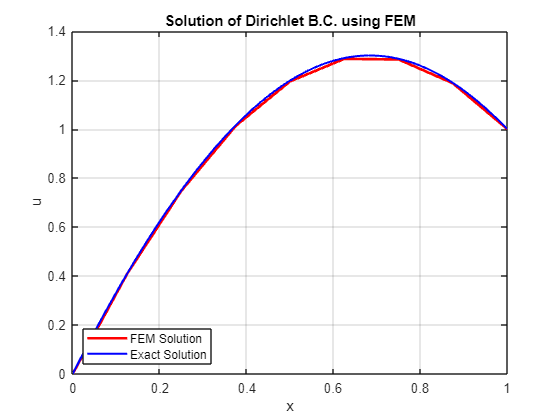

%Plot the FDM Solution and the actual solution
figure;
plot(X, u_D_bc, "r", "LineWidth", 2, "DisplayName", "FEM Solution"); 
hold on;
fplot(x, exact_sol_f, [0 1], "b", "LineWidth", 1.5, "DisplayName", "Exact Solution");
xlabel("x");
ylabel("u");
title("Solution of Dirichlet B.C. using FEM");
legend('Location', 'southwest');
grid on;